**Pipeline:**

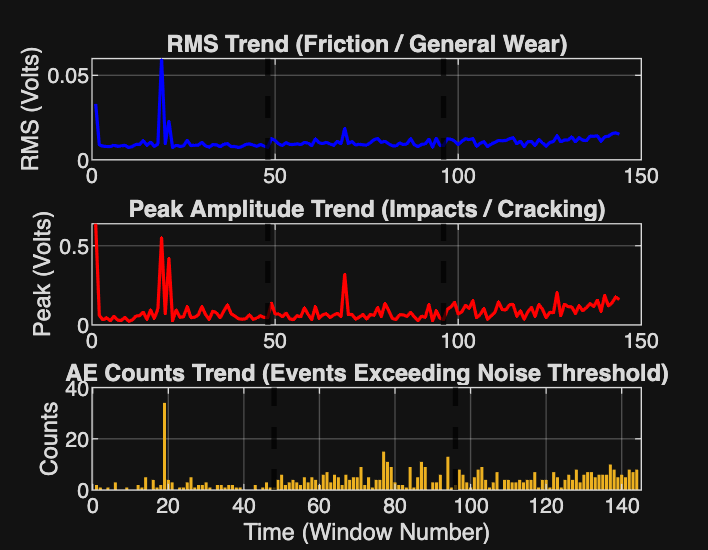

clear
clc
close all

%% 1. PARAMETERS & INITIALIZATION
fs = 4000;                % Sampling rate (Hz)
window_time = 0.1;        % 100 ms window
overlap = 0.0;            % 0% overlap for clear sequential trending

% File definitions
files = [
    "AE testing/a0016.bin"
    "AE testing/a0017.bin"
    "AE testing/a0018.bin"
];

win = round(window_time * fs);           
step = round(win * (1 - overlap));       

all_RMS = [];
all_Peak = [];
all_Counts = [];
file_boundaries = []; 

%% 2. PIPELINE: WINDOWING & FEATURE EXTRACTION
current_window_idx = 0;

for f = 1:length(files)
    filename = files(f);
    fid = fopen(filename, 'rb');
    
    if fid == -1
        fprintf("Cannot open file: %s. Check your current MATLAB directory.\n", filename);
        continue
    end

    % Read the 16-bit binary integer data
    data = fread(fid, Inf, 'uint16');
    fclose(fid);

    % Convert ADC integers to real Voltage (Assuming 12-bit ADC, 3.3V reference)
    signal = double(data) / 4096 * 3.3;   
    
    % Remove DC offset (Center the signal around 0 Volts)
    signal = signal - mean(signal);
    
    N = length(signal);
    
    % Define the Threshold for AE Counts 
    % We use 3x the standard deviation of the normal files to filter out background noise
    Threshold = 3.0 * std(signal); 

    for i = 1:step:N-win
        segment = signal(i:i+win-1);
        
        % 1. RMS (Overall Friction)
        val_rms = sqrt(mean(segment.^2));
        
        % 2. Peak Amplitude (Impacts)
        val_peak = max(abs(segment));
        
        % 3. AE Counts (Rate of Destruction)
        val_counts = sum(abs(segment) > Threshold);
        
        % Store features
        all_RMS = [all_RMS; val_rms];
        all_Peak = [all_Peak; val_peak];
        all_Counts = [all_Counts; val_counts];
        
        current_window_idx = current_window_idx + 1;
    end
    
    file_boundaries = [file_boundaries; current_window_idx];
end

%% 3. TREND VISUALIZATION 
if isempty(all_RMS)
    error("No data processed. Please ensure the files exist in the correct directory.");
end

time_axis = 1:length(all_RMS);
figure('Name', 'AE Condition Monitoring', 'Position', [100, 100, 900, 700]);

% Plot 1: RMS 
subplot(3, 1, 1);
plot(time_axis, all_RMS, 'b', 'LineWidth', 1.2);
ylabel('RMS (Volts)');
title('RMS Trend (Friction / General Wear)');
grid on; hold on;
for b = 1:length(file_boundaries)-1
    xline(file_boundaries(b), 'k--', 'LineWidth', 2);
end

% Plot 2: Peak Amplitude
subplot(3, 1, 2);
plot(time_axis, all_Peak, 'r', 'LineWidth', 1.2);
ylabel('Peak (Volts)');
title('Peak Amplitude Trend (Impacts / Cracking)');
grid on; hold on;
for b = 1:length(file_boundaries)-1
    xline(file_boundaries(b), 'k--', 'LineWidth', 2);
end

% Plot 3: AE Counts
subplot(3, 1, 3);
bar(time_axis, all_Counts, 'FaceColor', [0.9290, 0.6940, 0.1250], 'EdgeColor', 'none');
ylabel('Counts');
xlabel('Time (Window Number)');
title('AE Counts Trend (Events Exceeding Noise Threshold)');
grid on; hold on;
for b = 1:length(file_boundaries)-1
    xline(file_boundaries(b), 'k--', 'LineWidth', 2);
end